# EE141 Digital Signal Processing

# Lab 4: Sampling and Aliasing

# Lab Section: 022

# Name: Buddy Ugwumba SID: 862063029

## Objective

Develop an understanding of the fundamentals of samping from continuous-time signals. This is done by comparison of signals with inadequate sampling rates with or without anti-aliasaing filters. This will be complemented by emulation of practical reconstruction filters in the discrete-time domain. 

### Question 1

#### a)

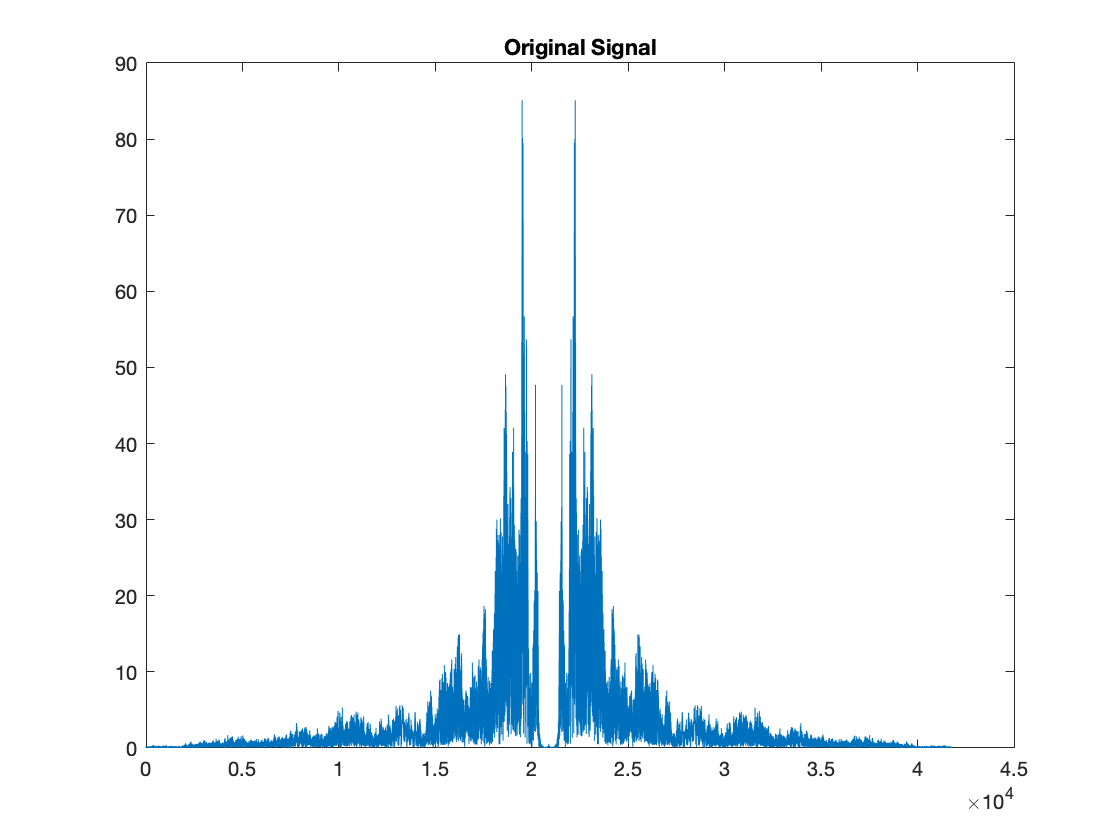

load ertem_voice.mat
p = audioplayer(audio_sample,fs);
play(p)
figure
plot(fftshift(abs(fft(audio_sample))))
title("Original Signal")
hold on

#### b)

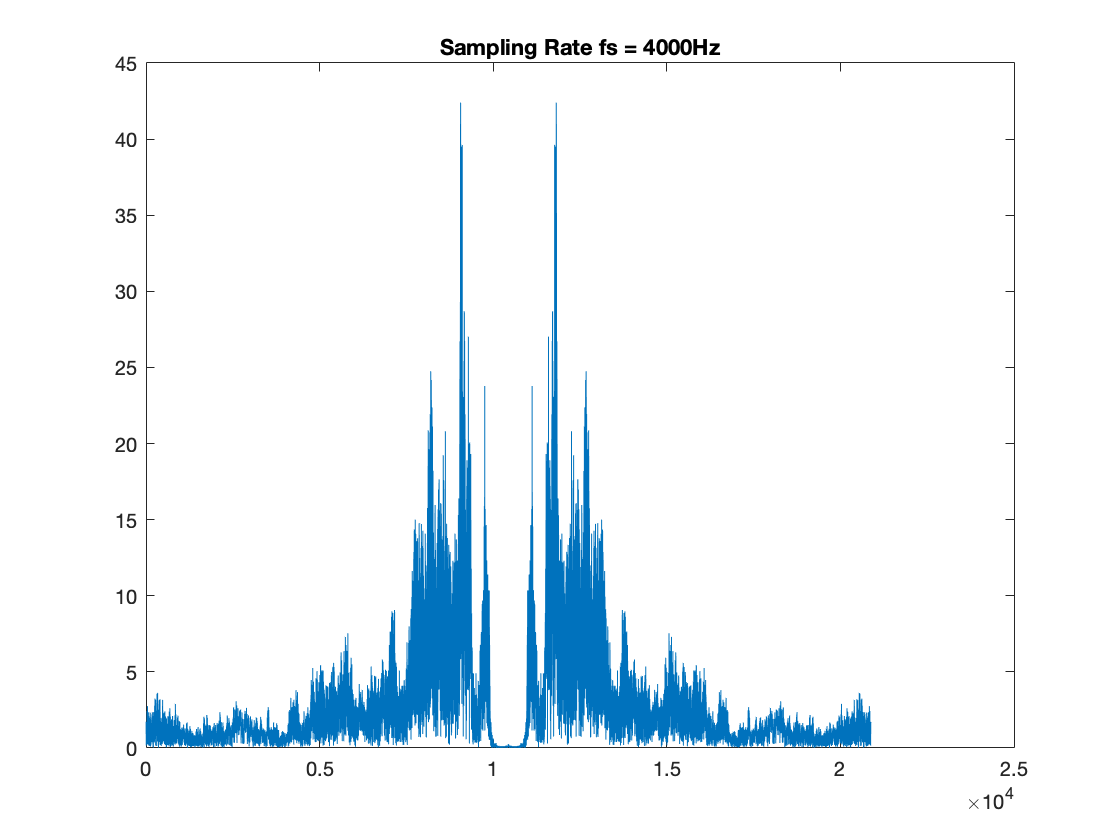

New_fs_4000Hz = audio_sample(1:2:end);
play_4000Hz = audioplayer(New_fs_4000Hz, fs/2);
play(play_4000Hz)
figure
plot(fftshift(abs(fft(New_fs_4000Hz))))
title("Sampling Rate fs = 4000Hz")
hold on

Compared with plot a), the magnitude of the signal is decreased, the bandwidth of the signal has also decreased by about half. Yes, I can hear the aliasing effects when I play the audio 

#### c)

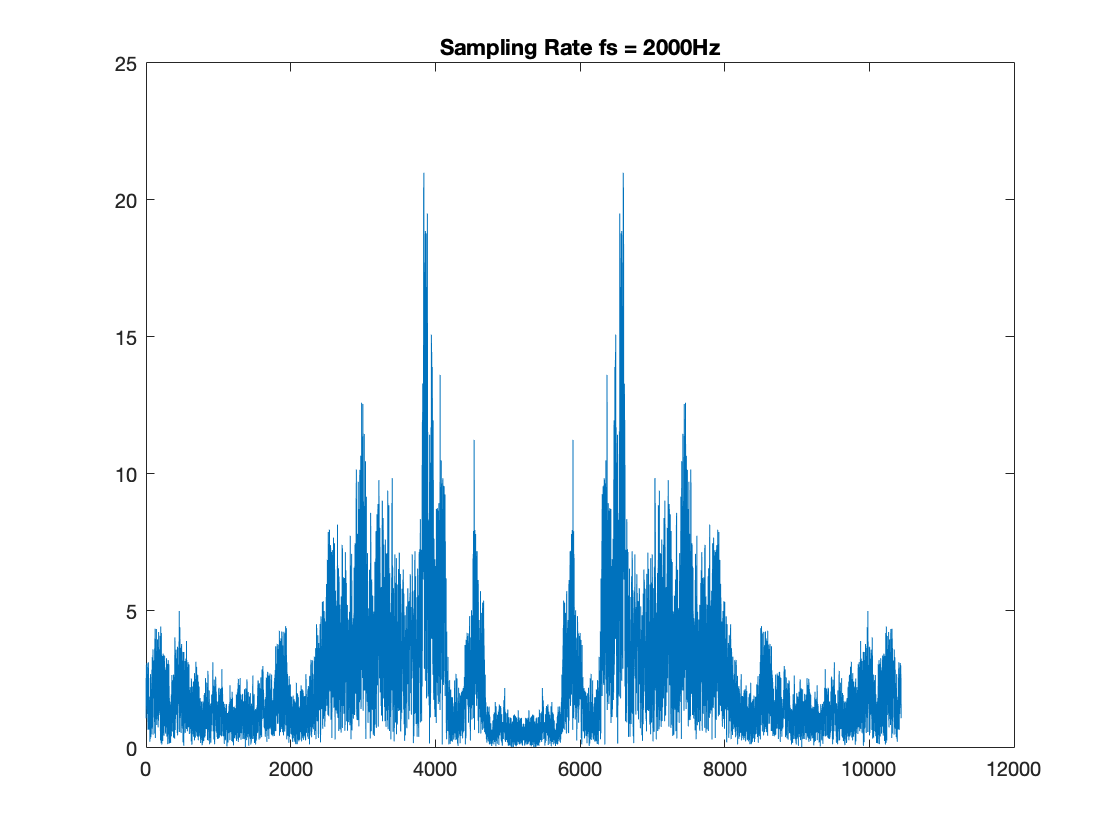

New_fs_2000Hz = audio_sample(1:4:end);
play_2000Hz = audioplayer(New_fs_2000Hz, fs/4);
play(play_2000Hz)
figure
plot(fftshift(abs(fft(New_fs_2000Hz))))
title("Sampling Rate fs = 2000Hz")
hold on

New_fs_1000Hz = audio_sample(1:8:end);
play_1000Hz = audioplayer(New_fs_1000Hz, fs/8);

play_1000Hz =   audioplayer with properties:

          SampleRate: 1000
       BitsPerSample: 16
    NumberOfChannels: 1
            DeviceID: -1
       CurrentSample: 1
        TotalSamples: 5220
             Running: 'off'
            StartFcn: []
             StopFcn: []
            TimerFcn: []
         TimerPeriod: 0.0500
                 Tag: ''
            UserData: []
                Type: 'audioplayer'


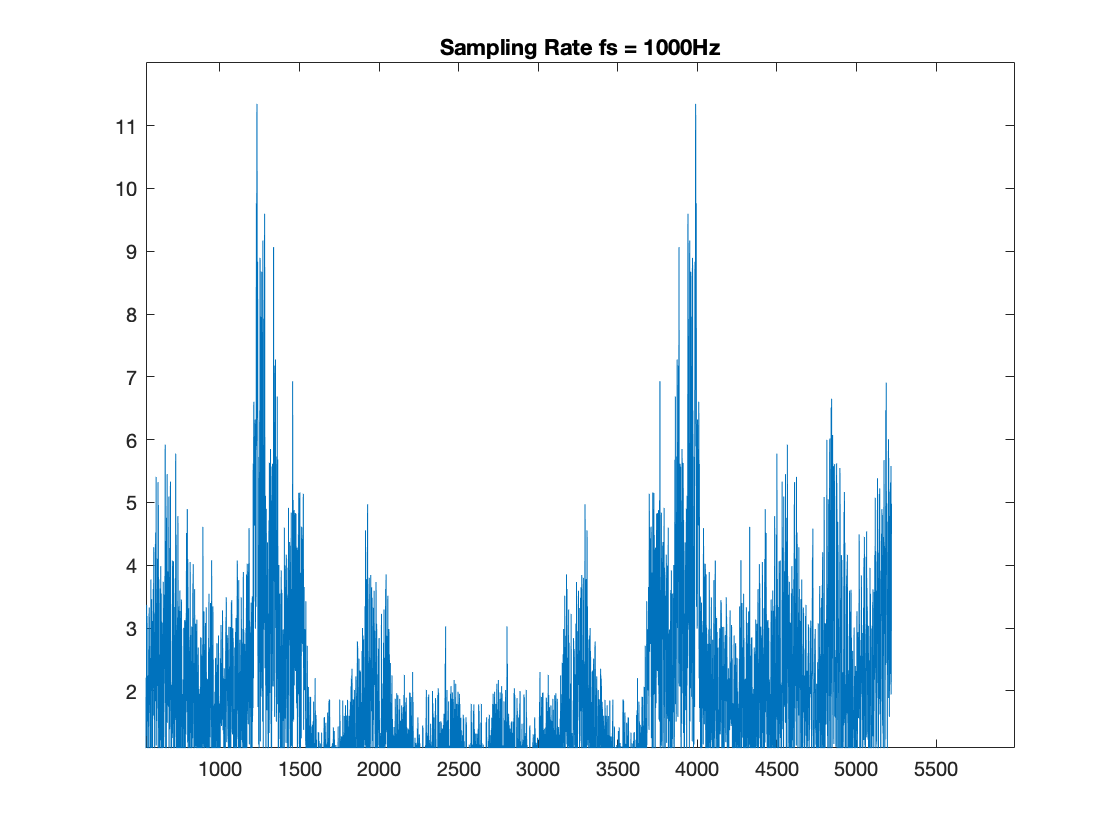

play(play_1000Hz)
figure
plot(fftshift(abs(fft(New_fs_1000Hz))))
title("Sampling Rate fs = 1000Hz")
hold on

With sampling rates $f_s =2,000\mathrm{Hz}$ and $f_s =1000\mathrm{Hz}$, I do observe more and more activity at high frequencies that did not appear before. The aliasing effect also becomes more and more present. This leads me to assume that the more activity at frequencies the greater the aliasing affect. 

#### d)

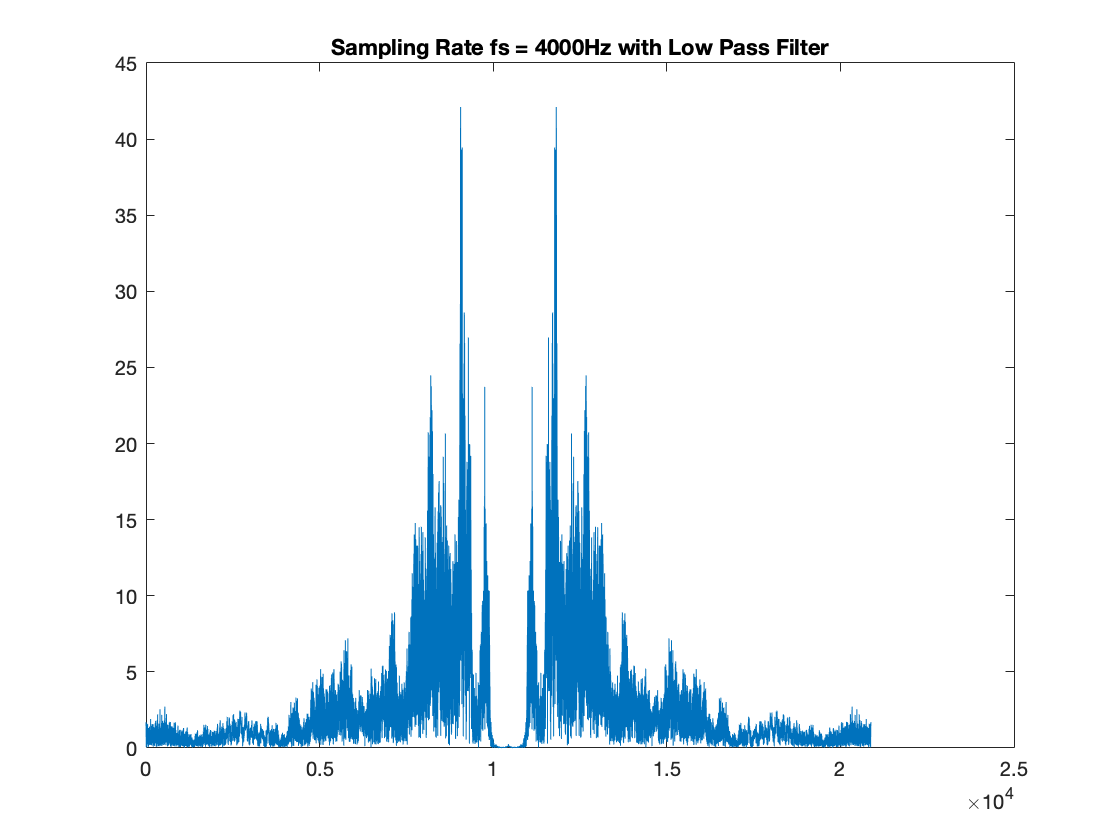

h_4000Hz = [1 1]/2;
h_2000Hz = [1 1 1 1]/4;
h_1000Hz = [1 1 1 1 1 1 1 1]/8;

fs_4000Hz_LowPassFilter = conv(audio_sample,h_4000Hz);
fs_4000Hz_LowPassFilter = fs_4000Hz_LowPassFilter(1:2:end);
play_4000Hz_LowPassFilter = audioplayer(fs_4000Hz_LowPassFilter,fs/2);
%play(play_4000Hz_LowPassFilter)
figure
plot(fftshift(abs(fft(fs_4000Hz_LowPassFilter))))
title("Sampling Rate fs = 4000Hz with Low Pass Filter")

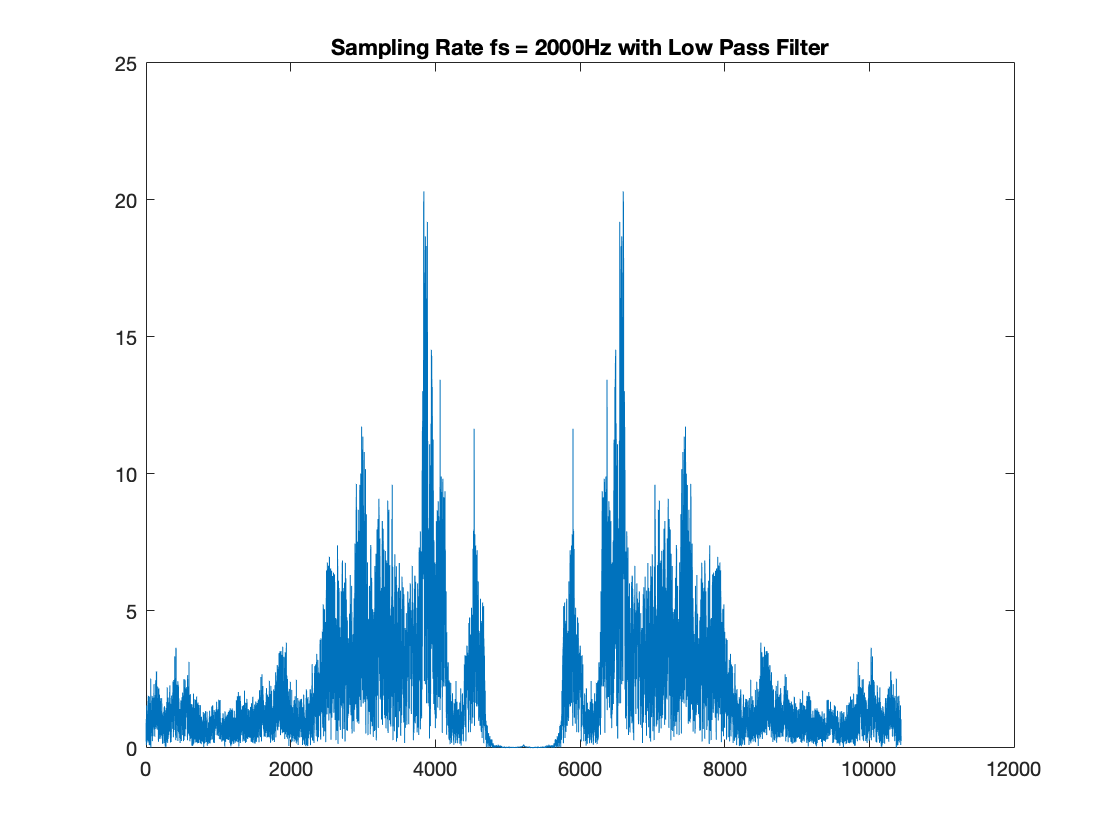

fs_2000Hz_LowPassFilter = conv(audio_sample,h_2000Hz);
fs_2000Hz_LowPassFilter = fs_2000Hz_LowPassFilter(1:4:end);
play_2000Hz_LowPassFilter = audioplayer(fs_2000Hz_LowPassFilter,fs/4);
%play(play_2000Hz_LowPassFilter)
figure
plot(fftshift(abs(fft(fs_2000Hz_LowPassFilter))))
title("Sampling Rate fs = 2000Hz with Low Pass Filter")

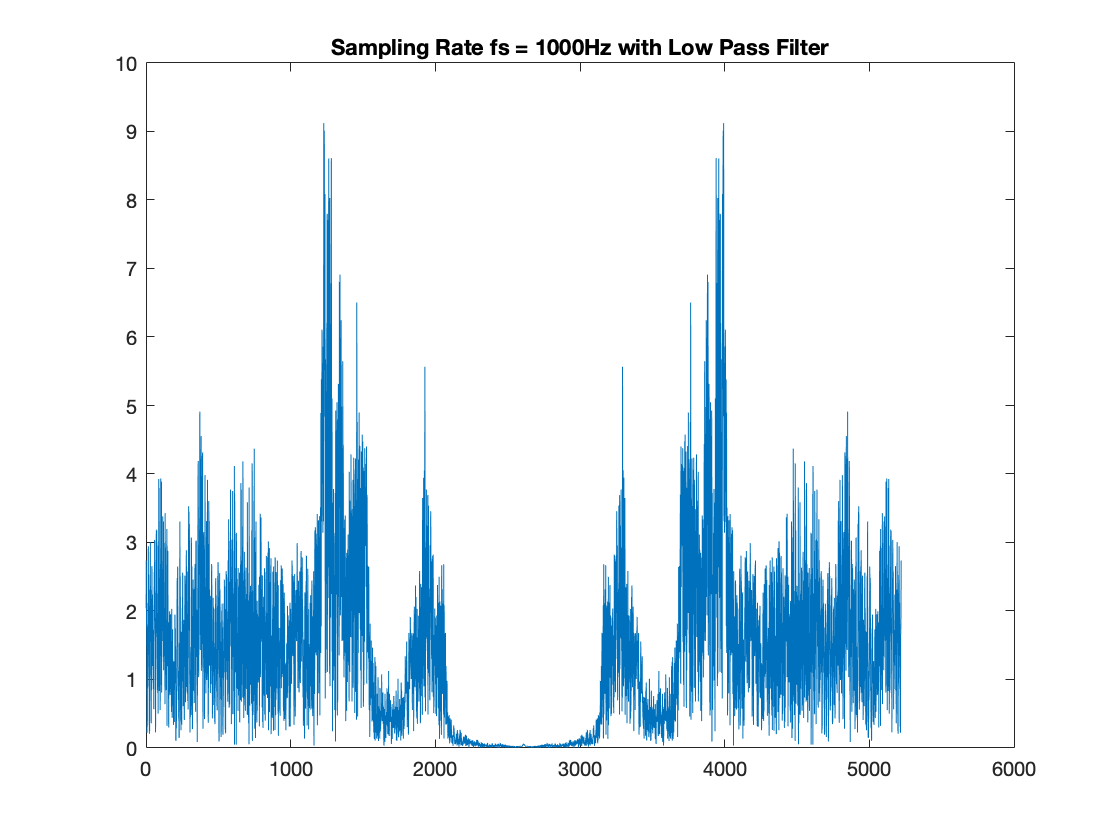


fs_1000Hz_LowPassFilter = conv(audio_sample,h_1000Hz);
fs_1000Hz_LowPassFilter = fs_1000Hz_LowPassFilter(1:8:end);
play_1000Hz_LowPassFilter = audioplayer(fs_1000Hz_LowPassFilter,fs/8);
play(play_1000Hz_LowPassFilter)
figure
plot(fftshift(abs(fft(fs_1000Hz_LowPassFilter))))
title("Sampling Rate fs = 1000Hz with Low Pass Filter")

The reason why these filters yield better results than no filtering is because they help to limit the bandwidth of the sampled frequency. I do not see the replicas as prominently. I do not believe that I hear the same aliasing effects, what I hear is a lowpass filtered version of the signal. 

### Question 2

#### a)

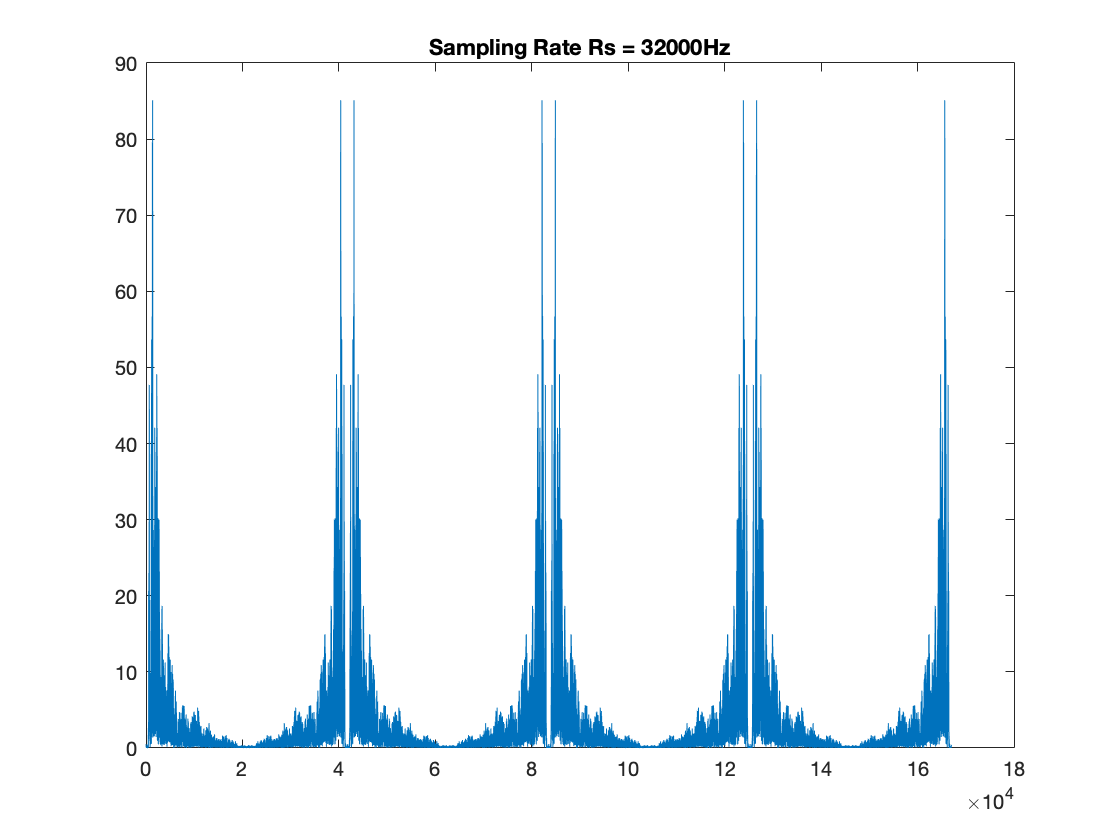

fs_32000Hz = upsample(audio_sample,4);
play_32000Hz = audioplayer(fs_32000Hz, fs*4);
play(play_32000Hz)
plot(fftshift(abs(fft(fs_32000Hz))))
title("Sampling Rate Rs = 32000Hz")

### b)

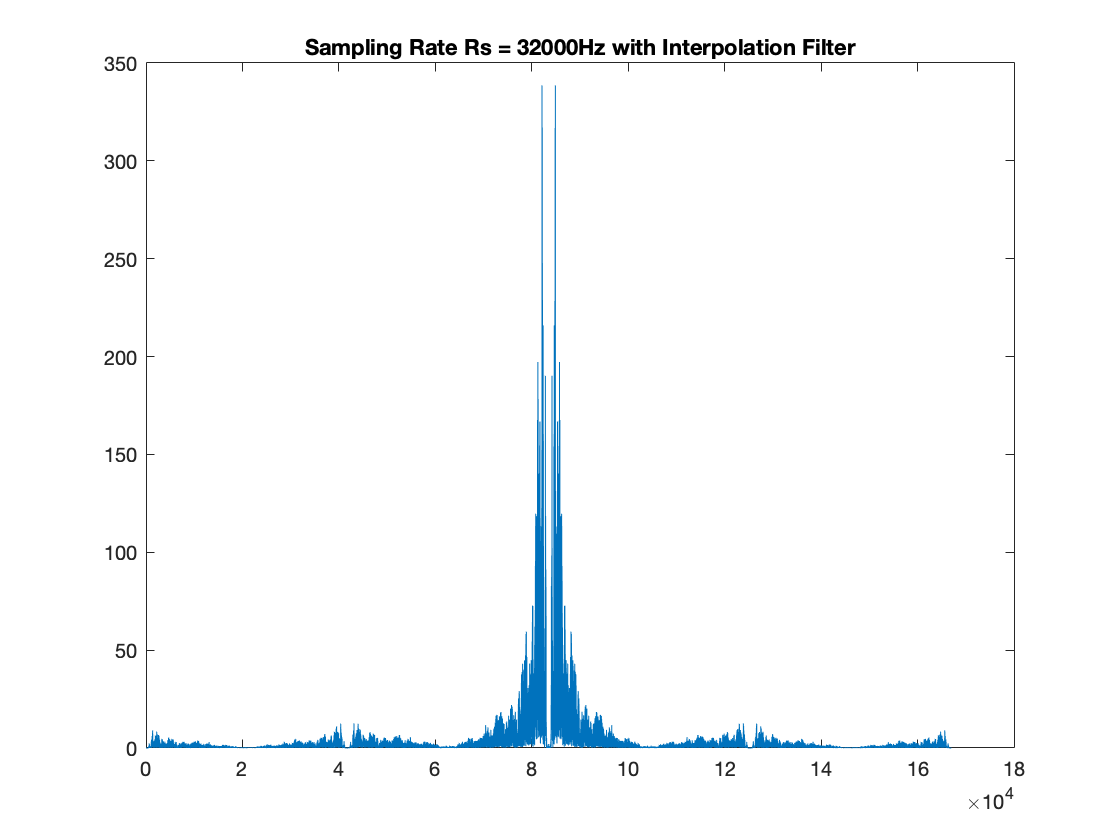

h_interpolationF = [1 1 1 1];
fs_32000Hz_interpolationF = conv(fs_32000Hz, h_interpolationF);
play_32000Hz_interpolationF = audioplayer(fs_32000Hz_interpolationF, fs*4);
play(play_32000Hz_interpolationF)
plot(fftshift(abs(fft(fs_32000Hz_interpolationF))))
title("Sampling Rate Rs = 32000Hz with Interpolation Filter")

Yes, I hear a slight mechanical sound. 

#### c)

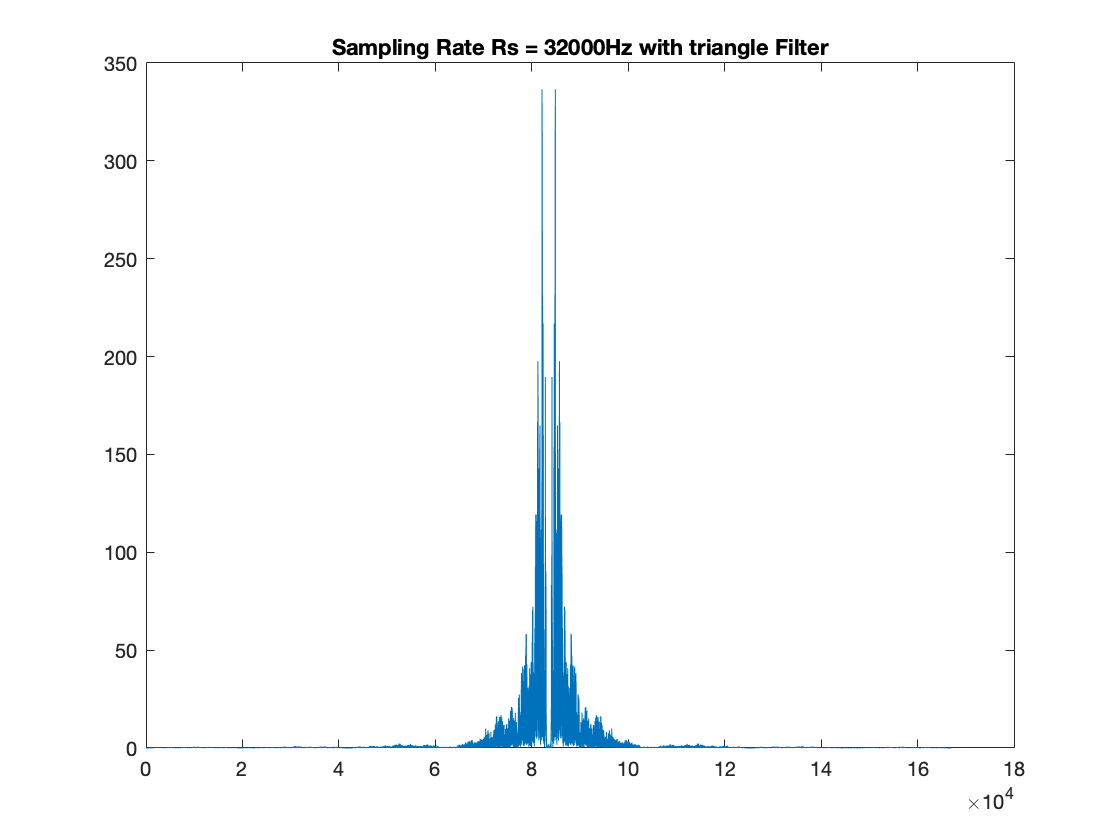

h_triangleF = [.25 .5 .75 1 .75 .5 .25];
fs_32000Hz_triangleF = conv(fs_32000Hz, h_triangleF);
play_32000Hz_triangleF = audioplayer(fs_32000Hz_triangleF, fs*4);
play(play_32000Hz_triangleF)
plot(fftshift(abs(fft(fs_32000Hz_triangleF))))
title("Sampling Rate Rs = 32000Hz with triangle Filter")

Yes, the unwanted replica's are suppressed much better and the prresenece of the mechanical sound lessoned.

#### d)

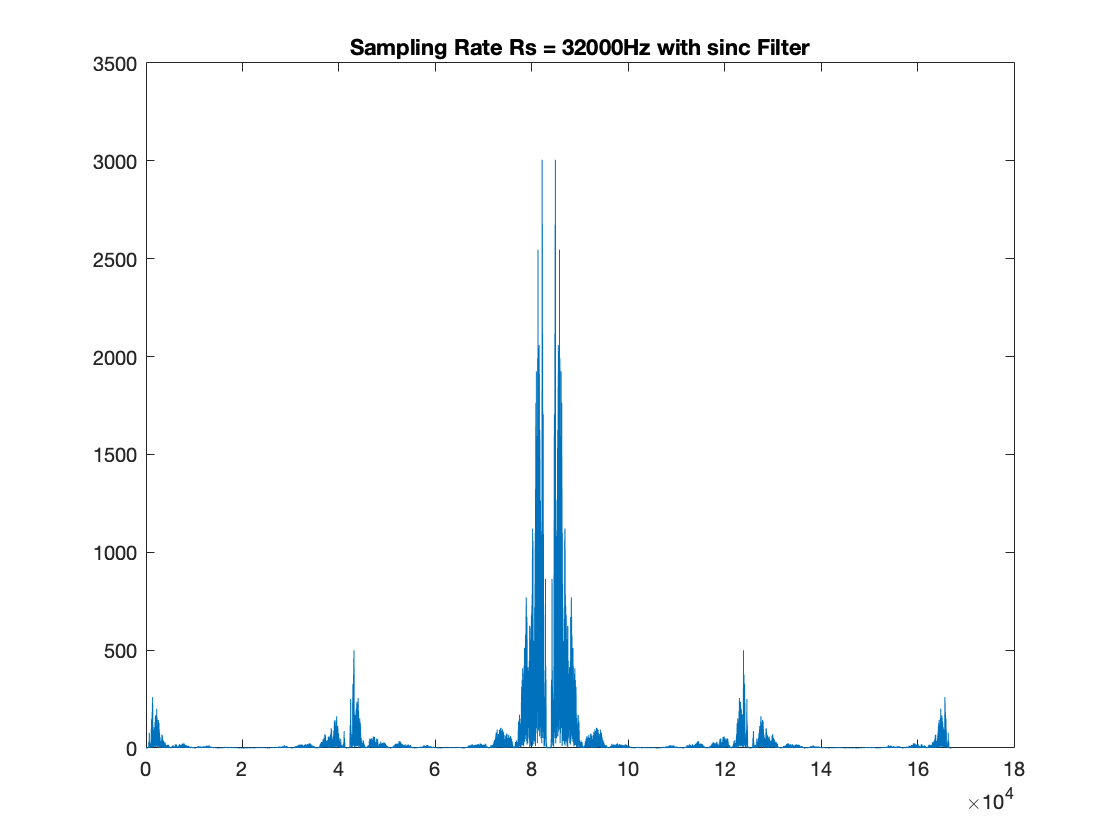

h_sincF =(-4:.25:4);
fs_32000Hz_sincF = conv(fs_32000Hz, h_sincF);
play_32000Hz_sincF = audioplayer(fs_32000Hz_sincF, fs*4);
play(play_32000Hz_sincF)
plot(fftshift(abs(fft(fs_32000Hz_sincF))))
title("Sampling Rate Rs = 32000Hz with sinc Filter")

The unwanted replicas are not supressed better than in c), and the mechanical sound is more present. 